A = [0 1;-5 -2];
B = [0;3];
C = [0 1];
D = 0;
Ts = 0.25;
sysd = ss(A,B,C,D,Ts);

% openExample('shared_tracking_fusion/Estimate2DTargetStatesUsingTrackingKFExample')
rng(2021);    % For repeatable results
dt = 0.2;     % seconds
simTime = 20; % seconds
tspan = 0:dt:simTime;
trueInitialState = [30; 2; 40; 2]; % [x;vx;y;vy]
processNoise = diag([0; 1; 0; 1]); % Process noise matrix
measureNoise = diag([4 4]); % Measurement noise matrix
numSteps = length(tspan);
trueStates = NaN(4,numSteps);
trueStates(:,1) = trueInitialState;
estimateStates = NaN(size(trueStates));
F = [1 dt 0  0;
     0  1 0  0; 
     0  0 1 dt;
     0  0 0  1];
H = [1 0 0 0;
     0 0 1 0];
for i = 2:length(tspan)
    trueStates(:,i) = F*trueStates(:,i-1) + sqrt(processNoise)*randn(4,1);  
end
measurements = H*trueStates + sqrt(measureNoise)*randn(2,numSteps);
figure
plot(trueStates(1,1),trueStates(3,1),"r*",DisplayName="True Initial")
hold on
plot(trueStates(1,:),trueStates(3,:),"r",DisplayName="Truth")
plot(measurements(1,:),measurements(2,:),"kx",DisplayName="Measurements")
xlabel("x (m)")
ylabel("y (m)")
axis image
filter = trackingKF(MotionModel="2D Constant Velocity",State=[40; 0; 160;0], ...
    MeasurementModel=H,MeasurementNoise=measureNoise)

filter =   trackingKF with properties:

               State: [4×1 double]
     StateCovariance: [4×4 double]

         MotionModel: '2D Constant Velocity'
        ControlModel: []
        ProcessNoise: [4×4 double]

    MeasurementModel: [2×4 double]
    MeasurementNoise: [2×2 double]

     EnableSmoothing: 0


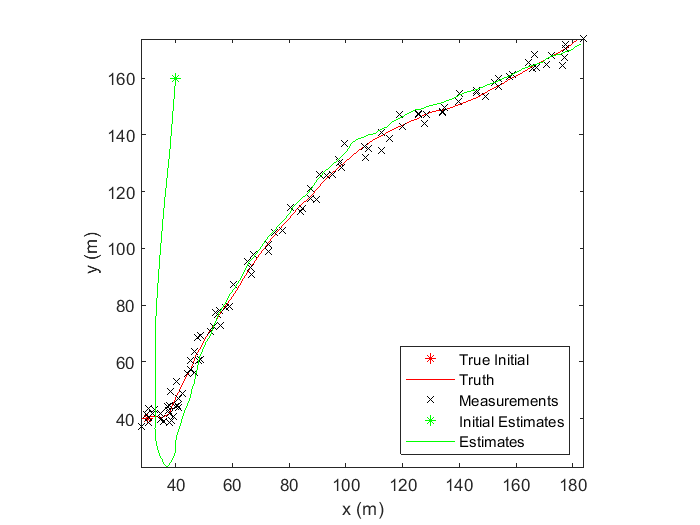

estimateStates(:,1) = filter.State;
for i=2:length(tspan)
    predict(filter,dt)
    estimateStates(:,i) = correct(filter,measurements(:,i));
end
plot(estimateStates(1,1),estimateStates(3,1),"g*",DisplayName="Initial Estimates")
plot(estimateStates(1,:),estimateStates(3,:),"g",DisplayName="Estimates")
legend(Location="southeast")

sysd = ss(F,[],H,[],dt);

bound = 0.001;
hfilter = hinf.HinfSteadyStateFilter(sysd,[],[],[],bound);
x = NaN(size(trueStates));
x(:,1) = hfilter.State;
for i = 2:length(tspan)
    x(:,i) = hfilter.Gain*x(:,i-1);
    estimateStates(:,i) = correct(filter,measurements(:,i));
end
% hfilter.StateCovariance
% filter.StateCovariance